# Impedance Controller of Gait

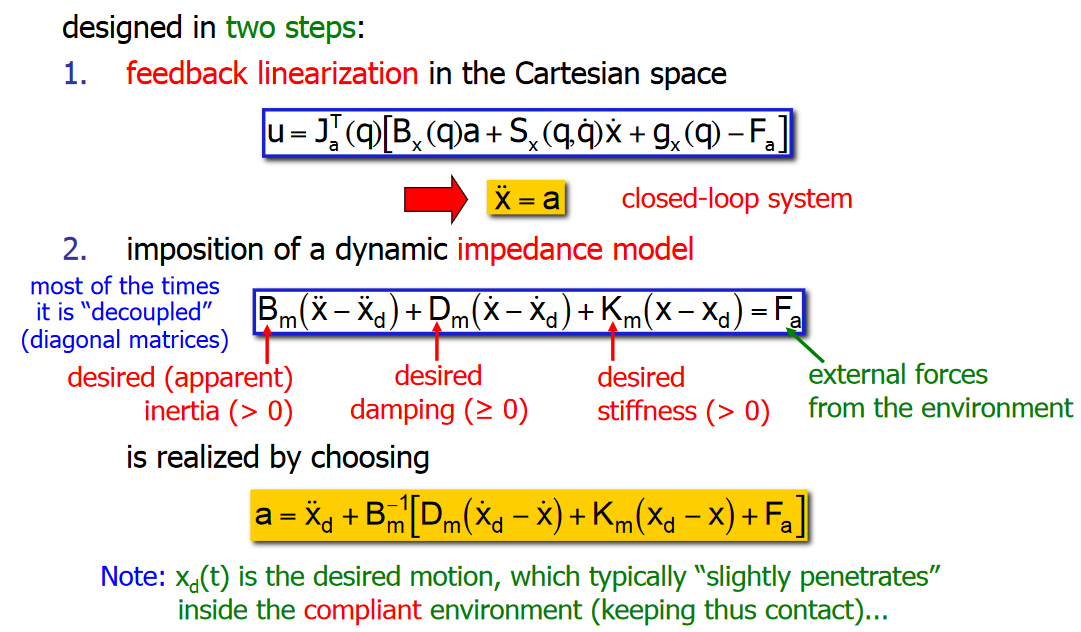

## For 1D prismatic motion of a block, with ground friction

syms m b x xd Fa Xd t
syms Bm Dm Km % desired impedance
syms Ydd Yd Y % desired motion

Real system parameters

m = 3, b = 2

m = 3

b = 2

Desired system impedance

Bm = 3.5, Dm = 10, Km = 300

Bm = 3.5000

Dm = 10

Km = 300

Define dynamic system model

Q = x, Qd = xd, X = x, Xd = xd

$$Q = x$$

$$Qd = \mathrm{xd}$$

$$X = x$$

$$Xd = \mathrm{xd}$$

Bx = m, Sx = b, gx = 0

Bx = 3

Sx = 2

gx = 0

Analytical Jacobian

Ja = jacobian(X, Q)

$$Ja = 1$$

Control Law

a = Ydd + Bm \ (Dm*(Yd - Xd) + Km*(Y - X) + Fa)

$$a = \frac{2\,\mathrm{Fa}}{7}+\frac{600\,Y}{7}+\frac{20\,\mathrm{Yd}}{7}+\mathrm{Ydd}-\frac{600\,x}{7}-\frac{20\,\mathrm{xd}}{7}$$

u = Ja.' * (Bx*a + Sx*Xd + gx - Fa);
pretty(simplify(u))

1800 Y   Fa   60 Yd           1800 x   46 xd
------ - -- + ----- + 3 Ydd - ------ - -----
   7      7     7                7       7



ufunc = matlabFunction(u, 'Vars', {Q, Qd, Fa, Y, Yd, Ydd}, 'File', 'impedance_controller')

ufunc =     @impedance_controller


## 3D Shin

syms x y z xd yd zd

n = 3;
Fa = sym('F', [n 1]);
Y = sym('Y', [n 1]);
Yd = sym('Yd', [n 1]);
Ydd = sym('Ydd', [n 1]);

setup

Desired Impedance

Bm = 2*eye(3), Dm = 1*eye(3), Km = diag([200 200 500])

Bm =      2     0     0
     0     2     0
     0     0     2


Dm =      1     0     0
     0     1     0
     0     0     1


Km =    200     0     0
     0   200     0
     0     0   500


Q = [x; y; z], Qd = [xd; yd; zd], X = Q, Xd = Qd

$$Q = \left(\begin{array}{c} x\\ y\\ z \end{array}\right)$$

$$Qd = \left(\begin{array}{c} \mathrm{xd}\\ \mathrm{yd}\\ \mathrm{zd} \end{array}\right)$$

$$X = \left(\begin{array}{c} x\\ y\\ z \end{array}\right)$$

$$Xd = \left(\begin{array}{c} \mathrm{xd}\\ \mathrm{yd}\\ \mathrm{zd} \end{array}\right)$$

mass = 985*shinL*pi*shinr^2;
Bx = mass * eye(3), Sx = zeros(3), gx = zeros(3,1)

Bx =     3.0945         0         0
         0    3.0945         0
         0         0    3.0945


Sx =      0     0     0
     0     0     0
     0     0     0


gx =      0
     0
     0


Ja = jacobian(X, Q)

$$Ja = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

a = Ydd + Bm \ (Dm*(Yd - Xd) + Km*(Y - X) + Fa)

$$a = \left(\begin{array}{c} \frac{F_{1}}{2}+100\,Y_{1}+\frac{{\mathrm{Yd}}_{1}}{2}+{\mathrm{Ydd}}_{1}-100\,x-\frac{\mathrm{xd}}{2}\\ \frac{F_{2}}{2}+100\,Y_{2}+\frac{{\mathrm{Yd}}_{2}}{2}+{\mathrm{Ydd}}_{2}-100\,y-\frac{\mathrm{yd}}{2}\\ \frac{F_{3}}{2}+250\,Y_{3}+\frac{{\mathrm{Yd}}_{3}}{2}+{\mathrm{Ydd}}_{3}-250\,z-\frac{\mathrm{zd}}{2} \end{array}\right)$$

u = Ja.' * (Bx*a + Sx*Xd + gx - Fa)

$$u = \left(\begin{array}{c} \frac{197\,\pi \,\left(\frac{F_{1}}{2}+100\,Y_{1}+\frac{{\mathrm{Yd}}_{1}}{2}+{\mathrm{Ydd}}_{1}-100\,x-\frac{\mathrm{xd}}{2}\right)}{200}-F_{1}\\ \frac{197\,\pi \,\left(\frac{F_{2}}{2}+100\,Y_{2}+\frac{{\mathrm{Yd}}_{2}}{2}+{\mathrm{Ydd}}_{2}-100\,y-\frac{\mathrm{yd}}{2}\right)}{200}-F_{2}\\ \frac{197\,\pi \,\left(\frac{F_{3}}{2}+250\,Y_{3}+\frac{{\mathrm{Yd}}_{3}}{2}+{\mathrm{Ydd}}_{3}-250\,z-\frac{\mathrm{zd}}{2}\right)}{200}-F_{3} \end{array}\right)$$

ufunc = matlabFunction(u, 'Vars', {Q, Qd, Fa, Y, Yd, Ydd})

ufunc =     @(in1,in2,in3,in4,in5,in6)[-in3(1,:)+pi.*(in3(1,:).*(1.0./2.0)+in4(1,:).*1.0e2+in5(1,:).*(1.0./2.0)+in6(1,:)-in1(1,:).*1.0e2-in2(1,:).*(1.0./2.0)).*(1.97e2./2.0e2);-in3(2,:)+pi.*(in3(2,:).*(1.0./2.0)+in4(2,:).*1.0e2+in5(2,:).*(1.0./2.0)+in6(2,:)-in1(2,:).*1.0e2-in2(2,:).*(1.0./2.0)).*(1.97e2./2.0e2);-in3(3,:)+pi.*(in3(3,:).*(1.0./2.0)+in4(3,:).*2.5e2+in5(3,:).*(1.0./2.0)+in6(3,:)-in1(3,:).*2.5e2-in2(3,:).*(1.0./2.0)).*(1.97e2./2.0e2)]
